# Moving Horizon Estimation Unconstrained - EKF Update Terminal Cost

This Live Script allow to visualize the results of estimation performed through MHE algorithm with:

- search direction compute via 'BFGS' method.

- Terminal Cost Updated through EKF update rule.

clear 
close all
clc

rng('default')

## Set Path

addpath("simulation");
addpath("Optimization/UncOpt");
addpath("Optimization/ConsOpt");
addpath("simulation/SimulationData");

Urban = 0; % by default set it to 0, constrained problem only in highway
real_meas = 0; % set to 1 to see performnces on more realistic data
max_time = 25; % maximum to 25
min_time = 0.5; % better to avoid setting it to 0
Con = 0; % set to 1 if dealing with a constrained optimization problem

## Generate Measurement and Ground Truth Datasets

[ymeas_camera,ymeas_radar,N,time_vec,GT_state,min_index,max_index,~,~] = get_meas(Con,Urban,real_meas,min_time,max_time);

## Filtering Algorithm

### Parameters of the Algorithm

nz = 5; % number of states
ny = 4; % number of measured output
nu = 2; % number of inputs (disturbances)
Ts = 0.1; % Filter/sensors sampling time
Ts_sim = 0.1; % 0.01; % simulation sampling time, for optimization with simulation error method

#### Camera Covariance Matrix

As a general rule, lower values than radar

camera_x_var = 10; % better if higher
camera_y_var = 1; % better if lower
camera_v_x_var = 10; % better if higher
camera_v_y_var = 1; % better if lower
R_camera = diag([camera_x_var,camera_y_var,camera_v_x_var,camera_v_y_var])*eye(ny);


#### Radar Covariance Matrix

Higher values than camera

radar_x_var = 100; % better if lower
radar_y_var = 1000; % better if higher
radar_v_x_var = 100; % better if lower
radar_v_y_var = 1000; % better if higher
R_radar = diag([radar_x_var,radar_y_var,radar_v_x_var,radar_v_y_var])*eye(ny);

#### Process Covariance

long_acc_var = 1;
ang_acc_var = 1;
Q = diag([long_acc_var,ang_acc_var])*eye(nu);

#### Terminal Cost Covariance Matrix

A_terminal = 1e9*eye(nz);

#### Initial Guess

z_minus = [ymeas_radar(1,1);ymeas_radar(2,1);ymeas_radar(3,1);ymeas_radar(4,1);0.1]; % z(-M|1) initial state guess 

#### Optimizer Options

myoptions               =   myoptimset;
myoptions.display    	=	'Iter';
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-8;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'off';

### Filtering Algorithm

Msec            =   1;    % Seconds of Moving Horizon Estimator Window
MHE_interval    =   1;    % number of steps after which optimization routine is repeated

[z_est,d_est,comp_time] = MHE_Unc_EKF(Ts,Ts_sim,N,nz,ny,nu,Msec,MHE_interval,R_camera,R_radar,Q,A_terminal,z_minus,myoptions,ymeas_camera,ymeas_radar);

Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    2.10422e+09   3.58761e+02    1.00000e+00    1.00000e+00                0
        1    2.10945e+07   1.92112e+02    4.64513e-01    1.14133e-02               10
        2    3.80357e+06   1.50673e+02    2.15700e-01    2.87347e-02                8
        3    1.27366e+06   1.16040e+02    2.29856e-01    6.67589e-02                7
        4    1.61441e+05   1.05849e+02    8.78204e-02    4.43915e-02                7
        5    3.48751e+05   1.03903e+02    1.83867e-02    1.50771e-02                7
        6    1.36760e+03   1.03127e+02    7.47035e-03    3.85361e-02                7
        7    1.73118e+02   1.03090e+02    3.64234e-04    6.11126e-03                6
        8    8.05596e+04   1.01981e+02    1.07529e-02    1.34399e-02                3
        9    2.92910e+04   3.96330e+01    6.11369e-01    1.40867e-01                4
       10    2.44130e+01   3.89601e+01    1.69769e-02 

mean_computational_time = mean(comp_time(Msec/Ts + 1 : end))

mean_computational_time = 0.1175

## Plot Results

### Relative Position

#### $x$ - Coordinate

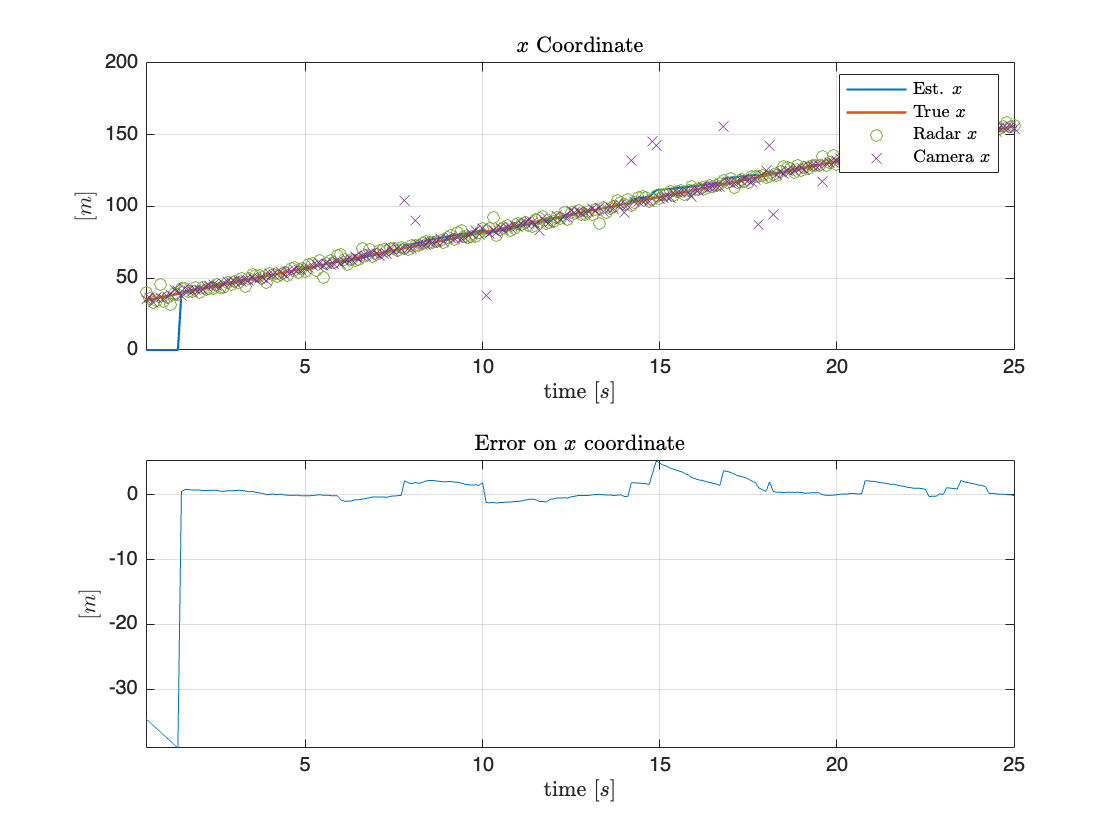

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(1,:),"LineWidth",1.1), hold on
plot(time_vec,GT_state(:,1),"LineWidth",1.2), hold on
plot(time_vec,ymeas_radar(1,:),"o","Color","#77AC30"),hold on
plot(time_vec,ymeas_camera(1,:),"x")
title('$x$ Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
legend('Est. $x$','True $x$','Radar $x$','Camera $x$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(1,:)-GT_state(:,1)'))
title('Error on $x$ coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;

xlim([min_time max_time]);
hold off

#### 
$$x-\textrm{RMSE}$$


x_rmse = rmse(z_est(1,:),GT_state(:,1)')

x_rmse = 7.5699

#### $y$ - Coordinate

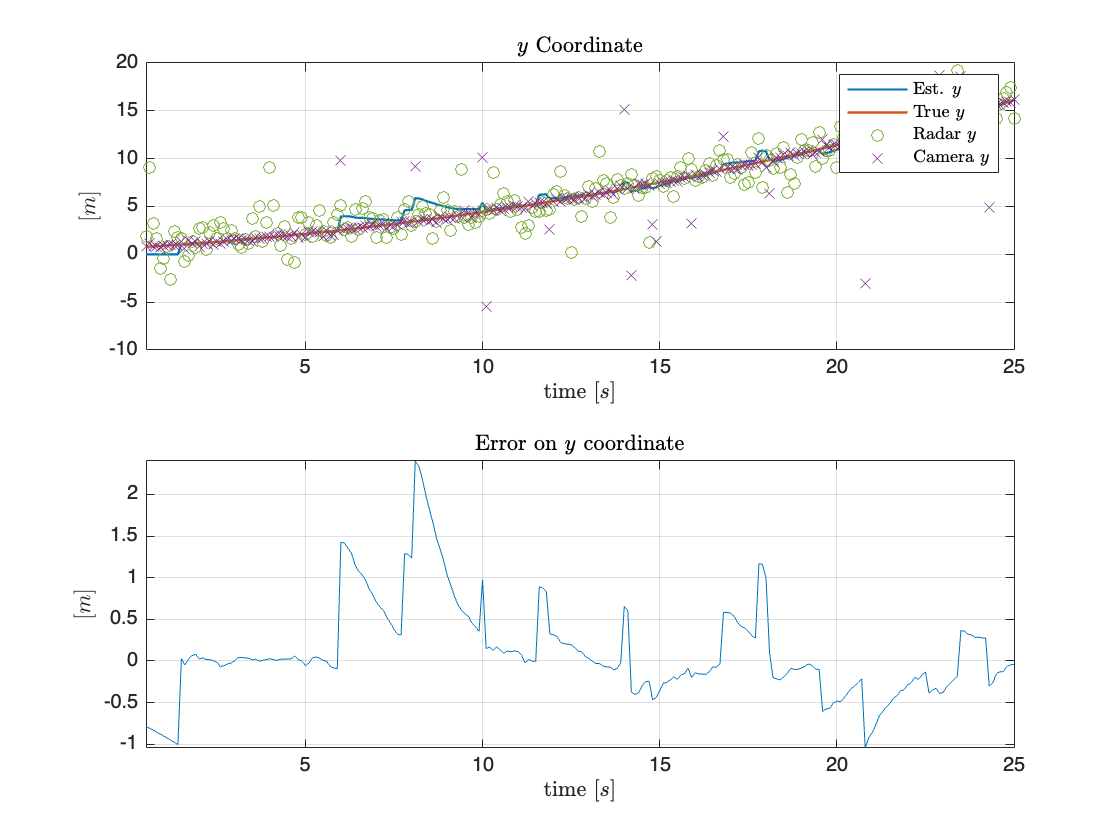

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(2,:),"LineWidth",1.1), hold on
plot(time_vec,GT_state(:,2),"LineWidth",1.2), hold on
plot(time_vec,ymeas_radar(2,:),"o","Color","#77AC30"),hold on
plot(time_vec,ymeas_camera(2,:),"x")
title('$y$ Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
legend('Est. $y$','True $y$','Radar $y$','Camera $y$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(2,:)-GT_state(:,2)'))
title('Error on $y$ coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off

#### 
$$y-\textrm{RMSE}$$


y_rmse = rmse(z_est(2,:),GT_state(:,2)')

y_rmse = 0.5939

### Velocities

#### 
$$v_x$$


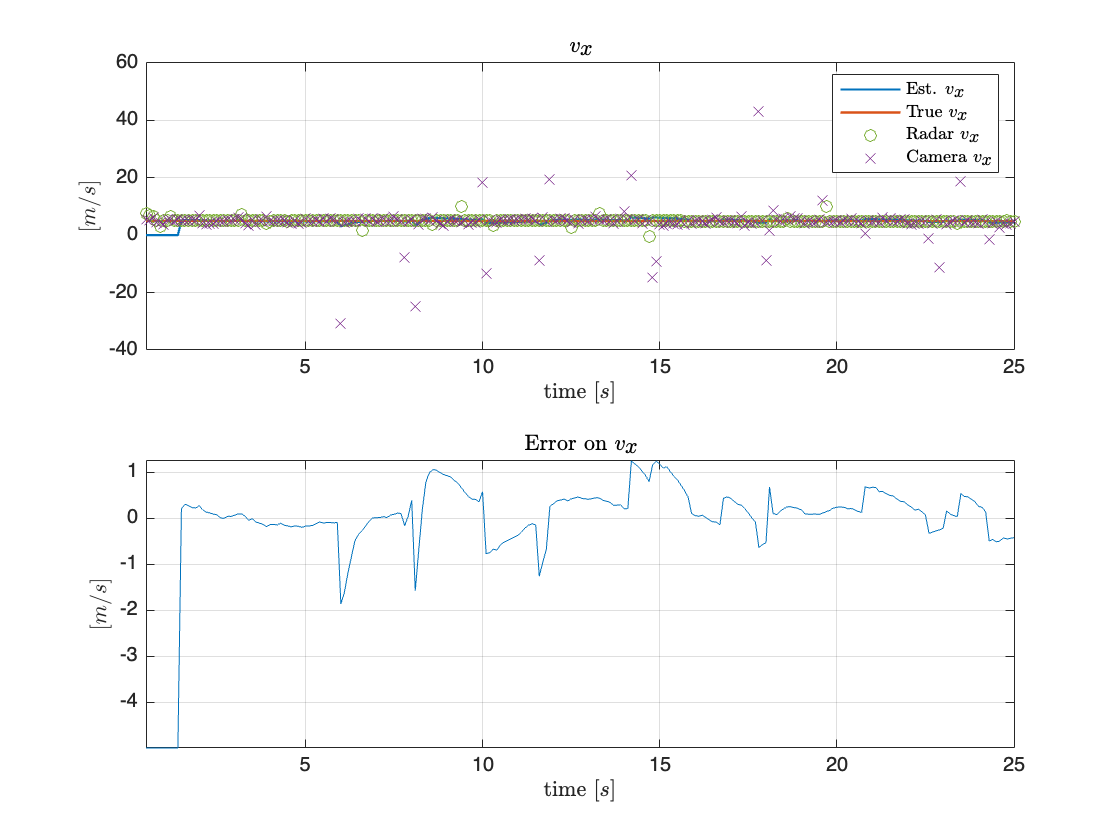

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(3,:),"LineWidth",1.1), hold on
plot(time_vec,GT_state(:,3),"LineWidth",1.2), hold on
plot(time_vec,ymeas_radar(3,:),"o","Color","#77AC30"),hold on
plot(time_vec,ymeas_camera(3,:),"x")
title('$v_x$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('Est. $v_x$','True $v_x$','Radar $v_x$','Camera $v_x$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(3,:)-GT_state(:,3)')), hold on
title('Error on $v_x$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')

linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$v_x -\textrm{RMSE}$$


v_x_rmse = rmse(z_est(3,:),GT_state(:,3)')

v_x_rmse = 1.1229

#### 
$$v_y$$


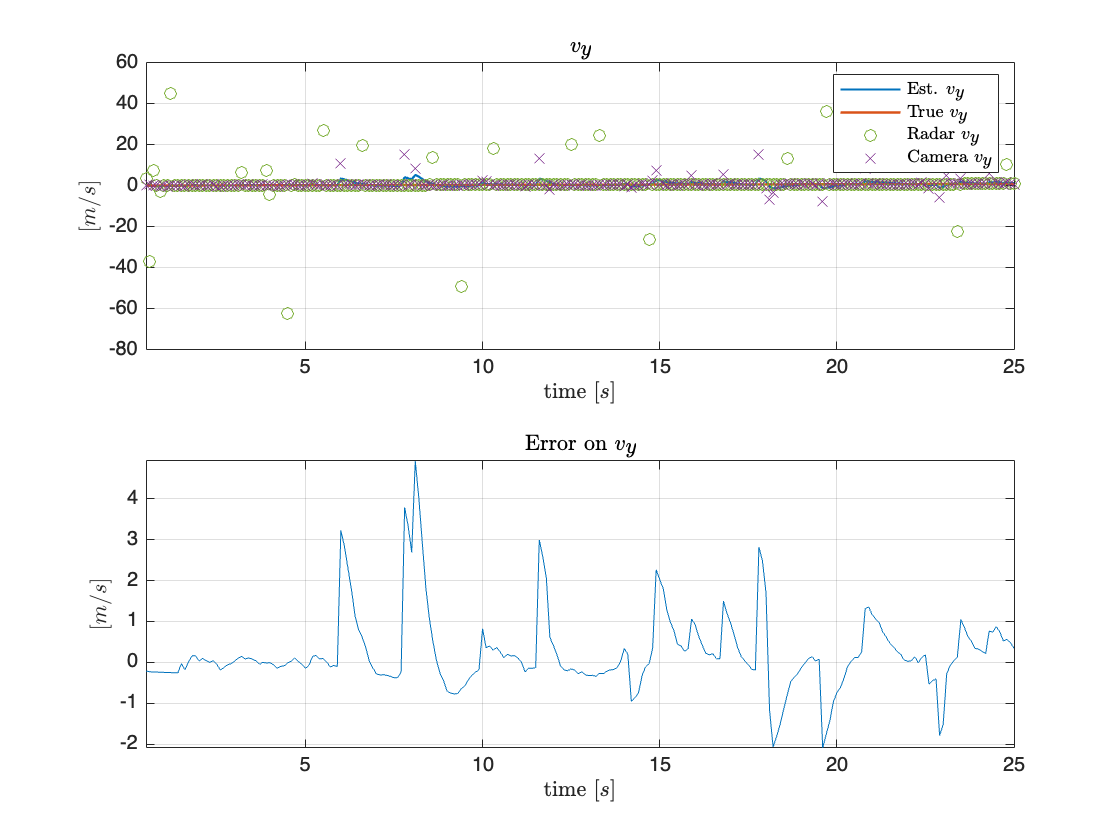

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(4,:),"LineWidth",1.1), hold on
plot(time_vec,GT_state(:,4),"LineWidth",1.2), hold on
plot(time_vec,ymeas_radar(4,:),"o","Color","#77AC30"),hold on
plot(time_vec,ymeas_camera(4,:),"x")
title('$v_y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('Est. $v_y$','True $v_y$','Radar $v_y$','Camera $v_y$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(4,:)-GT_state(:,4)'))
title('Error on $v_y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$v_{y\;} -\textrm{RMSE}$$


v_y_rmse = rmse(z_est(4,:),GT_state(:,4)')

v_y_rmse = 0.9746

#### Yaw Rate

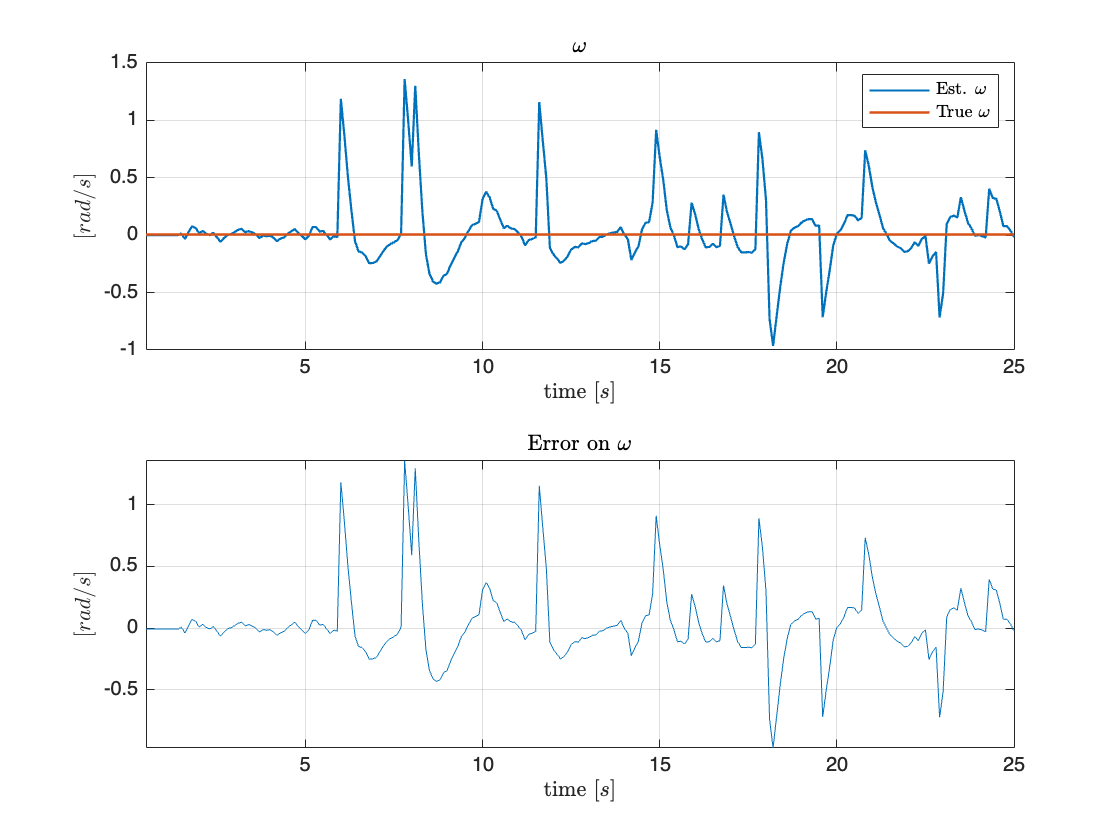

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(5,:),"LineWidth",1.1), hold on
plot(time_vec,GT_state(:,5),"LineWidth",1.2)
title('$\omega$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[rad/s]$','Interpreter','latex')
legend('Est. $\omega$','True $\omega$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(5,:)-GT_state(:,5)'))
title('Error on $\omega$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[rad/s]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$\textrm{Yaw}\;\textrm{Rate}-\textrm{RMSE}$$


yaw_rate_rmse = rmse(z_est(5,:),GT_state(:,5)')

yaw_rate_rmse = 0.2996

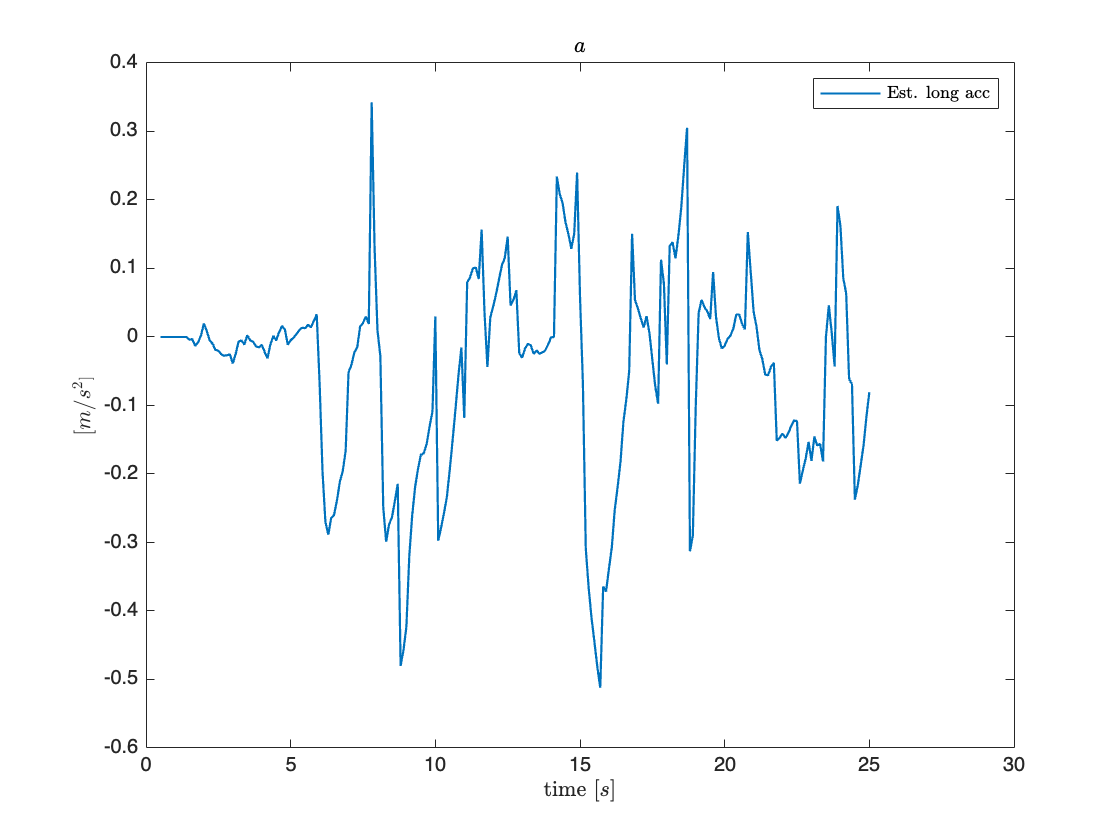

figure;
plot(time_vec,d_est(1,:),"LineWidth",1.1), hold on
title('$a$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s^2]$','Interpreter','latex')
legend('Est. long acc','Interpreter','latex')
hold off

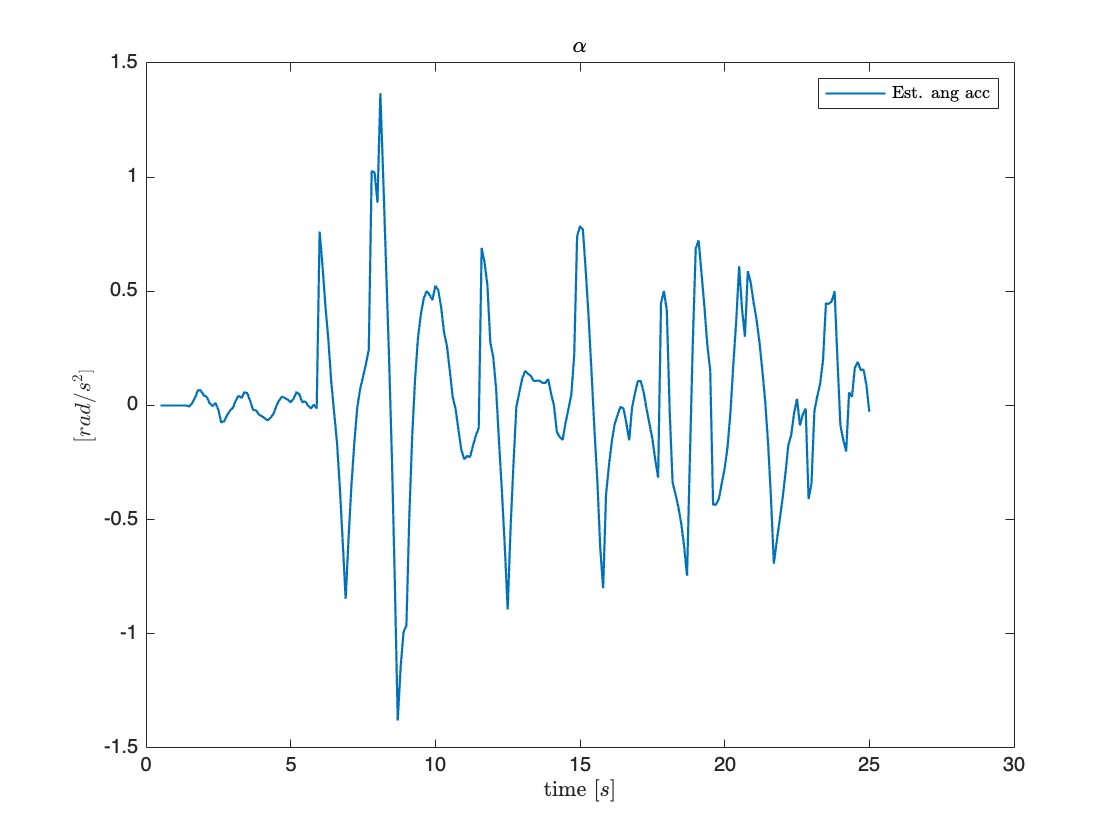

figure;
plot(time_vec,d_est(2,:),"LineWidth",1.1), hold on
title('$\alpha$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[rad/s^2]$','Interpreter','latex')
legend('Est. ang acc','Interpreter','latex')
hold off